# Lifting Surfaces Sizing

The purpose of this calculator is to size the lifting surfaces of the test dummy plane to be built over the Summer.

Sizing conditions not decided yet, perhaps **constraint analysis** could help to answer that question.

The plane has no purpose other than to practice manufactuing techniques and to prepare for a greater scale design. 

### Requirements

mass - 300 to 500 grams

wingspan < 4 feet

max altitude - 400 ft AGL

Hand launch take off

m = 0.42;   % gross mass (kg)
b = 1.2192/1.6  % wingspan (m), ~ 2.5 ft

b = 0.7620

### Conditions

The plane is set to be flown in the rec field (crosswinds not accounted for yet)

rho = 1.17; % air density (kg/m^3)
g = 9.18; % m/s^2

### Airfoil Data

NACA 4412 airfoil

cl_max = 1.2;

## Sizing

#### *Stall Sizing*

*Sizing wing to stall at a certain speed*

Vstall = 8; % lift off speed (m/s)
qstall = 1/2*rho*Vstall^2; 
Sstall = m*g/(cl_max*0.9)/qstall

Sstall = 0.0954

astall = Sstall/b

astall = 0.1251

ARstall = b/astall

ARstall = 6.0894

#### *Cruising Speed Sizing*

*L = cL*S*q*

Vcruise = 15; % cruise speed (m/s)
qcruise = 1/2*rho*Vcruise^2; % Pa
Scruise = m*g/(cl_max*0.81)/qcruise

Scruise = 0.0301

acruise = Scruise/b

acruise = 0.0395

ARcruise = b/acruise;

#### *Results*

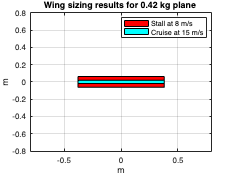

wingPlot = figure(); % wingPlot.Name = 'Wing Sizing Results';
tempx = [-b/2 b/2 b/2 -b/2]; tempy = [-astall/2 -astall/2 astall/2 astall/2];
fill(tempx, tempy, 'r')
hold on
tempy = [-acruise/2 -acruise/2 acruise/2 acruise/2];
fill(tempx, tempy, 'c'); grid on
hold off
to_label = "Stall at " + string(Vstall) + " m/s ";
cruise_label = "Cruise at " + string(Vcruise) + " m/s";
fig_title = "Wing sizing results for " + string(m) + " kg plane ";
xlim([-0.8 0.8]); ylim([-0.8 0.8]);
legend(to_label, cruise_label); xlabel('m'); ylabel('m')
title(fig_title)